% Load the training data 
data = load("D:\college\FYP\Scripts\Object_Detection\ACF\version\v2\signs_trainingData.mat");
signsDataset = data.signs_trainingData;

% Split the dataset into training, validation, and test sets. 
% Select 60% of the data for training, 10% for validation, 
% and the rest for testing the trained detector.
rng(0)
shuffledIndices = randperm(height(signsDataset));
idx = floor(0.6 * height(signsDataset));

trainingIdx = 1:idx;
trainingDataTbl = signsDataset(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = signsDataset(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = signsDataset(shuffledIndices(testIdx),:);

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,'TrafficSign'));

imdsValidation = imageDatastore(validationDataTbl{:,'imageFilename'});
bldsValidation = boxLabelDatastore(validationDataTbl(:,'TrafficSign'));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,'TrafficSign'));


% Combine image and box label datastores.
trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);


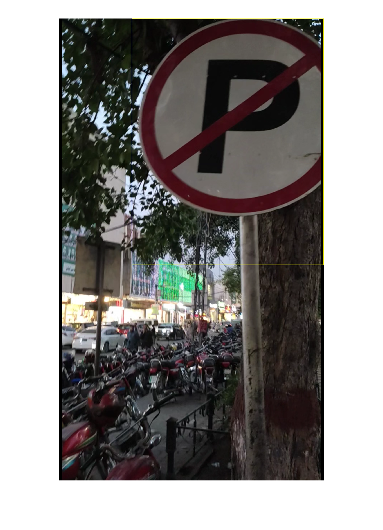

% Display one of the training images and box labels.
data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

## Create Faster R-CNN Detection Network

inputSize = [224 224 3];
preprocessedTrainingData = transform(trainingData, @(data)preprocessData(data,inputSize));
numAnchors = 3;
anchorBoxes = estimateAnchorBoxes(preprocessedTrainingData,numAnchors)

Error using estimateAnchorBoxes>iCheckBoxesFromDatastore
Invalid transform function defined on datastore.

Error in estimateAnchorBoxes>iParseInputs (line 164)
    boxes = iCheckBoxesFromDatastore(datastore);

Error in estimateAnchorBoxes (

**Load a pretrained model**

featureExtractionNetwork = resnet50;
featureLayer = 'activation_40_relu';
numClasses = width(signsDataset)-1;
lgraph = fasterRCNNLayers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

## Data Augmentation

augmentedTrainingData = transform(trainingData,@augmentData);

% Read the same image multiple times and display the augmented training data.
augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},'rectangle',data{2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData,'BorderSize',10)


## Preprocess Training Data

trainingData = transform(augmentedTrainingData,@(data)preprocessData(data,inputSize));
validationData = transform(validationData,@(data)preprocessData(data,inputSize));

% Read the preprocessed data.
data = read(trainingData);

% Display the image and box bounding boxes.
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

## Train Faster R-CNN

options = trainingOptions('sgdm',...
    'MaxEpochs',10,...
    'MiniBatchSize',2,...
    'InitialLearnRate',1e-3,...
    'CheckpointPath',tempdir,...
    'ValidationData',validationData);

[detector, info] = trainFasterRCNNObjectDetector(trainingData,lgraph,options, ...
        'NegativeOverlapRange',[0 0.3], ...
        'PositiveOverlapRange',[0.6 1]);

**Run the detector on one test image**

I = imread(testDataTbl.imageFilename{3});
I = imresize(I,inputSize(1:2));
[bboxes,scores] = detect(detector,I);

% Display the results.
I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
figure
imshow(I)

## Evaluate Detector Using Test Set

% Apply the same preprocessing transform to the test data as for the training data.
testData = transform(testData,@(data)preprocessData(data,inputSize));

% Run the detector on all the test images.
detectionResults = detect(detector,testData,'MinibatchSize',4);   

% Evaluate the object detector using the average precision metric.
[ap, recall, precision] = evaluateDetectionPrecision(detectionResults,testData);

% The precision/recall (PR) curve highlights 
% how precise a detector is at varying levels of recall.
figure
plot(recall,precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f', ap))


## Supporting Functions

function data = augmentData(data)
% Randomly flip images and bounding boxes horizontally.
tform = randomAffine2d('XReflection',true);
sz = size(data{1});
rout = affineOutputView(sz,tform);
data{1} = imwarp(data{1},tform,'OutputView',rout);

% Sanitize boxes, if needed. This helper function is attached as a
% supporting file. Open the example in MATLAB to open this function.
data{2} = helperSanitizeBoxes(data{2});

% Warp boxes.
data{2} = bboxwarp(data{2},tform,rout);
end

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to targetSize.
sz = size(data{1},[1 2]);
scale = targetSize(1:2)./sz;
data{1} = imresize(data{1},targetSize(1:2));

% Sanitize boxes, if needed. This helper function is attached as a
% supporting file. Open the example in MATLAB to open this function.
data{2} = helperSanitizeBoxes(data{2});

% Resize boxes.
data{2} = bboxresize(data{2},scale);
end